# Introduction to Linear Regression Models

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

In this script, we explore linear regression models and use real-world data to analyze and predict relationships between variables. We will explore engineering applications of linear regression models in the [Practice Linear Regression](matlab:open('./TryRegressionSoln.mlx')) script.

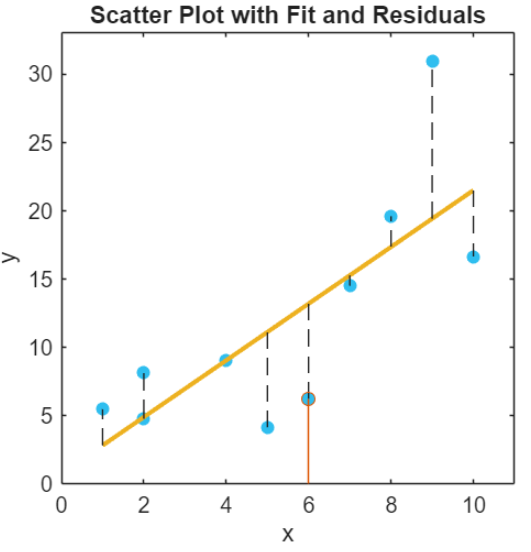

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction in which you will explore the visualization of a concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Simple Linear Regression

Suppose you have collected data on how the temperature of a metal rod, the dependent variable, changes over time when exposed to a heat source, the independent variable. To analyze this data to understand the relationship between time and temperature and make predictions, you can apply regression analysis to model and interpret the data.

.

**Simple linear regression** is the ideal statistical method for modeling the linear relationship between temperature and time, as it captures the linear relationship between one dependent variable and one independent variable. It is called *simple* because it involves only one predictor, the time the rod is exposed to heat in our example, and *linear* because the relationship is assumed to be a straight line. The straight line is represented by the equation:

$y=\beta_1x+\beta_0$       ($\star$)

where 

- $y$ is the dependent variable

- $x$ is the independent variable

- $\beta_0$ is the y-intercept

- $\beta_1$ is the slope

*Regression* is a statistical technique used to estimate the relationship that best captures the relationship between inputs and outputs, so we can predict future values of $y$ given new values of $x$.

The goal of **simple linear regression** is to find a function that best fits the data and can be used to predict future values of the dependent variable based on new inputs. There are infinitely many lines we must consider in search of the best fit. The tools of linear regression will help you make an optimal choice quickly. Before we consider the mathematics, let's first consider a small selection of possibilities. 

  **Try**. Find the line that best captures the data in the scatter plot.

- Click the **Display Data** button.

- Check the box(es) to choose the fit(s) you want to display.

 
load SampleData.mat x y % Load data
Fit = [false,true,false,false,false,false];
T = compareFits(x,y,Fit,1,0); % Call a function to plot data and display best fits.

 **Reflect**. Which best-fit line do you think best shows the overall pattern in the data, and why?

### **Perform Least-Squares Regression to Find "Best" Fit Line**

**Least squares regression** is a method for finding a function, usually a line, that best fits a set of data points. It does this by minimizing the total squared difference between the actual values. The residuals are squared to ensure the errors don't cancel out, and larger errors are penalized more heavily. The result of **least squares regression** is a line that balances all the data points as closely as possible, giving us a regression model we can use to make predictions. 

The least squares line is also known as the line of "**best" fit** or the **regression line****, **$y$, which is given mathematically as: 

$\hat{y}=\beta_1x+\beta_0$.    ( $\star$$\star$)

To help us distinguish between the actual value,$y$, and the predicted value, we add a "hat" to obtain the $\hat{y}$.

The **residual** is the difference between the observed value $y$ and the predicted value $\hat{y}$. The residual is represented on a plot as the vertical distance between each data point and the regression line, and is mathematically expressed as the difference between the observed value and the predicted value.

$\text{Residual}=\text{Actual}-\text{Predicted}=y-\hat{y}$. 

  **Try**. Visualize the residuals for each of the fits by selecting fits from the **dropdown menu** and then clicking the **button** to 'Visualize the Residuals'.

figure
load SampleData.mat x y % Load data
[yEquations,FitOptions] = SetEquations(x); %#ok<ASGLU>
Fit = yEquations(2);
if ~strcmp(Fit,"Select") && ~isequal(Fit,yEquations(1))
     
    T = compareFits(x,y,Fit,1,0); %#ok<NASGU> % Call a function to plot data,displays best fits.
else
    warning("Select a valid option.")
    return
end

 **Reflect.** What do you notice about the residuals? How do they help you determine which prediction is better than another?

### Sum of Squared Errors

To calculate the total error in a model, we would like to sum all the individual errors. However, if we simply add up residuals, we can end up with a small or even zero value when positive and negative errors cancel each other out, giving the impression of a better prediction than the model actually provides. By squaring the residuals before summing them, we prevent positive and negative values from offsetting one another. The sum of squared residuals can only be zero when no error is present at all. For that reason, the **sum of squared errors (SSE****) **is used to measure the total deviation between the actual values and those predicted by the model.


$$SSE=\sum_{i=1}^{n}{(y_i-(\beta_0+\beta_1x_i))^2=\sum_{i=1}^{n}{(y_i-\hat{y_i})^2$$


where $y_i$ is the actual value of the dependent variable corresponding to the $i^\text{th}$ data sample out of $n$ total samples, and $\beta_1x+\beta_0$, or $\hat{y_i}$ is the predicted value corresponding to the $i^\text{th}$ data sample out of $n$ total samples.

  **Try**. Review the **SSE** table and the graph to decide which model fits best.    

- Select a Fit from the **dropdown menu **below.

- Click the 'View SSE table and the Corresponding Best Fit' **button.**

figure
load SampleData.mat x y % Load data
[yEquations,FitOptions] = SetEquations(x);
Fit = yEquations(2);
 
T = compareFits(x,y,Fit,1,1); % Call a function to plot data,displays best fits.

  **Exercise 1**. Which fit is the best fit based on the **SSE** value?

if exist("yEquations","var")
    option = yEquations(2);
     
    option = string(option);
    CheckAnswer("Exercise1",option); % Call a function to check the answer.
else
    warning("Select a best fit option from above.")
end

### Use Simple Linear Regression to Estimate a Home's Value

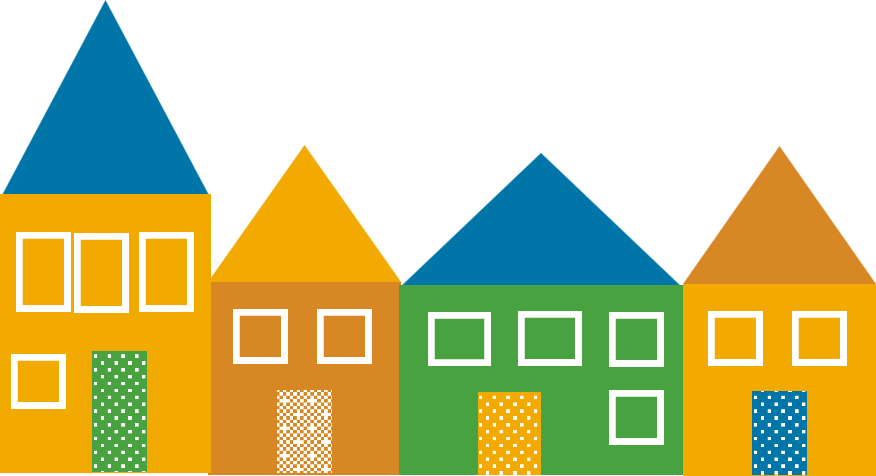

** Application. **Imagine you're estimating a home's value based on its square footage using data from recent sales in your neighborhood. While larger homes generally sell for more, the relationship isn't perfectly linear, as some large homes sell for less, and some smaller ones for more. To capture this trend, you can use simple linear regression, which models the relationship between the independent variable, the square footage, and the dependent variable, the price, with a straight line. The goal is to determine the line's coefficients so that the error between predicted and actual prices is minimized, helping you better understand how square footage influences home value.

 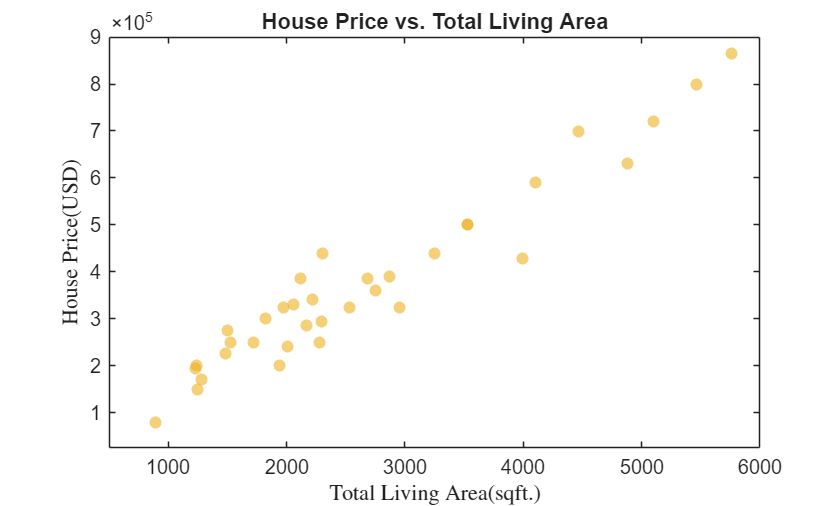

  **Try**. Find the Regression Line for the data plotted above.

- Click the **Plot the Regression Line** button.

- Adjust the $\beta_1$ and $\beta_0$ values, where $\beta_1$ is the slope, and $\beta_0$ is the y-intercept, to find an approximate straight line to model or fit the data.

load LinearData.mat x y
B1 = 129.5;% Set value for coefficient b1
B0 =  0.040;% Set value for coefficient b0
 
if strcmp(B0,"Select") || strcmp(B1,"Select")
    CreateStruct.Interpreter = "latex";
    CreateStruct.WindowStyle = "modal";
    syms beta_0 beta_1
    displayFormula(['"Select a value for "' "beta_0" '" and "' "beta_1" '"."']);
    return
else
    figure
    hScatterHouse = ScatterPlot(x,y);
    hold on
    FitHouse = B1.*x + B0;
    [~,~] = RegressFit(x,y,FitHouse);
    legend(["Data","Regression Line"],Location="northwest")
    hold off

    SSEHouse = round(sum((y - FitHouse).^2));
    SSEHouseSci = sprintf("%.3e",SSEHouse);
    xlabel("Total Living Area(sqft.)",Interpreter="latex")
    ylabel("House Price(USD)",Interpreter="latex")
    title("The sum of the squared errors (SSE) is: " + SSEHouseSci)
end

 **Reflect**. How confident are you that you found the best fit?

### Analytical Solution for Simple Linear Regression

Earlier, we focused on minimizing error visually. This meant creating a plot, looking at it, deciding on a new set of parameters to try, and repeating the process, which is not an efficient approach. Instead, we can use calculus to minimize the **SSE** and directly solve for the regression line coefficients $\beta_0$ and $\beta_1$. These coefficients define the slope and intercept of the line that best fits the data. Solving for them defines a model that minimizes the total squared differences between actual and predicted values. This process is at the heart of regression.

By substituting the linear model $y=\beta_1*x+\beta_0$, we can express  **simple linear regression** as the optimization problem of minimizing the total squared differences between the observed values and the predicted values: 

The equations are shown below:


$$\underset{\beta_0,\beta_1}{\min} \sum_{i=1}^{n} \left( y_i - (\beta_1 x_i+\beta_0 ) \right)^2$$


You can solve this analytically for $\beta_1$ and $\beta_0$ to get: 

   
$$\( 
\beta_1 = \frac{\sum_{i=1}^{n} (x_i - \bar{x})(y_i - \bar{y})}{\sum_{i=1}^{n} (x_i - \bar{x})^2} \qquad \text{and} \qquad
\beta_0 = \bar{y} - \beta_1 \bar{x} \qquad

(\star\star\star)$$


where 

$\bar{x}$ (xbar) is the average of all $x_i$

$\bar{y}$ (ybar) is the average of all $y_i$

$i$ indicates the individual data samples from a total of $n$ samples

Access a full [proof of ordinary least squares for simple linear regression](https://statproofbook.github.io/P/slr-ols.html#:~:text=RSS(%CE%B20,x2i)(5)) used to arrive at the equations for $\beta_0$ and $\beta_1$.

### Evaluate SSE: Guess vs. Optimal Regression

In this section, we compare your self‑selected “guess” for the regression line with the analytical solution derived from the equations above ( $\star$$\star$$\star$) using the following MATLAB code:

We calculate the **SSE** for both your guess and the true coefficients, then evaluate how far your guess deviates from the optimal values to illustrate how least squares identifies the best-fit line.

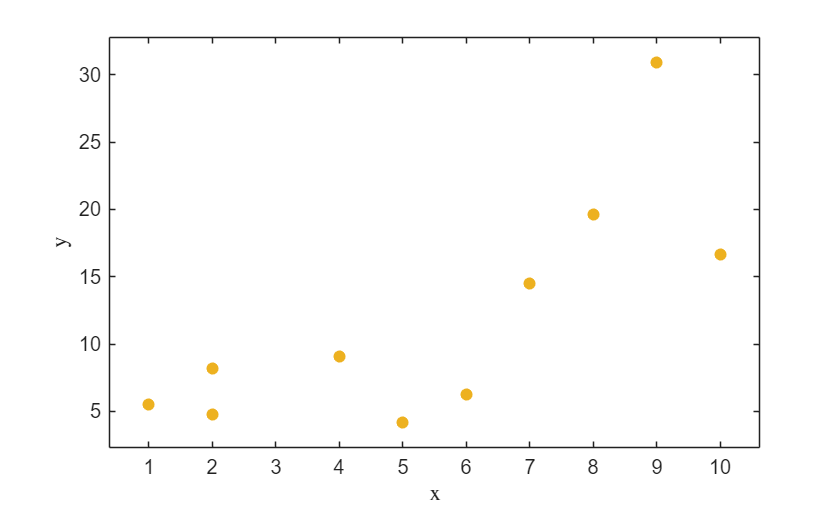

  **Exercise 2**. Test different values of $\beta_0$ and $\beta_1$to see how they change the fit and the **SSE. **Try to get the best fit possible. Recall, the equation for the regression line: 

$y = \beta_1 x + \beta_0$.

Select values for $\beta_0$ and $\beta_1$ below. Then click the **button **to validate your answer.

load SampleData.mat x y
b1Guess =2.075;
b0Guess =  0.7629;
if ~strcmp("Select",b1Guess) && ~strcmp("Select",b0Guess)
    evaluateLinearFit(x,y,b1Guess,b0Guess)
else
    warning("Select valid options for b0 and b1.")
    return
end
 

 **Reflect**. If you found the optimal fit for exercise 2, how did the SSE for that fit compare to the other models?

### Use the Regression Model to Predict Prices

Now that we have the coefficients ($\beta_0$,$\beta_1$), we can substitute them into our regression equation to predict future values. For example, our dataset includes homes up to 6,000 square feet. While we have prices for some square footage, others are missing—this is why we use a regression line: to estimate values where data is incomplete.

Before making predictions, keep these cautions in mind:

- **Stay within range**: Predict only for square footage within the range of your original data.

- **Visualize the fit**: Plot the data and the regression line to check how well it represents the trend.

- **Watch for outliers**: Extreme values can distort the regression line and lead to inaccurate predictions.

Let’s apply these cautions to make our predictions with our best-fit line. Suppose we want to predict the price of a house with 3,470 square feet. Here, square footage is the independent variable, and price is the dependent variable. Using our regression equation ( $\star$$\star$), we can calculate the estimated price.

  **Try**. Estimate the price of a 3,470 square foot home. 

load LinearData.mat x y
[xData,yData] = prepareCurveData(x,y);
[fitresult,~] = fit(xData,yData,"poly1");
b0 =fitresult.p2;
b1 = fitresult.p1;
SqFt= 3470;
 
Price = b1*SqFt+b0;
Price = round(Price,2);
import java.text.DecimalFormat
formatter = DecimalFormat('###,###'); % comma grouping
PriceForm = char(formatter.format(Price)); % convert Java string to MATLAB
SqFt = char(formatter.format(SqFt));
disp("The estimated price for "+ SqFt + " sqft. is $"+ PriceForm + ".")
% Plot the estimated price on the plot
h = plot(fitresult,xData,yData);
legend(h,"Data","Regression Line",Location="best");
hold on
SqFt = str2double(SqFt);
scatter(SqFt,Price,"d","filled",DisplayName="Estimated Price for "+ SqFt + " sqft.");
xlabel("Total Living Area (sqft.)",Interpreter="latex")
ylabel("House Price (USD)",Interpreter="latex")
hold off

 **Exercise 3. **Use the section above to predict the price of a 1,864 sqft. home.

CheckAnswer("Exercise3","$264,116")
 

## Interpreting Regression Model Performance: 95% Confidence Interval

Having identified the best fit line, we can deepen our understanding of the model by introducing the 95% confidence interval, which provides a measure of uncertainty around our estimates. We will review this before you try applying regression on your own. Residual plots reveal errors and patterns but not uncertainty around the regression line. The **95% confidence interval** addresses this by showing where the true line likely falls, offering a clear measure of reliability. On a scatter plot, it appears as a shaded band:

- narrow bands indicate precise predictions and strong features

- wide or uneven bands suggest noise or poor feature selection. 

  **Try**. Visualize a narrow and a wide 95% confidence interval by clicking the 'View Different Confidence Intervals' **button** below.

ConfInt;
 

### Try Linear Regression on Your Own

In this script, we have described the concepts and underpinnings of simple linear regression. Learn how to import a dataset in MATLAB, build a regression model for a lung ventilator, and use that model to predict future values in [Practice Linear Regression](matlab:open('./TryRegressionSoln.mlx')).

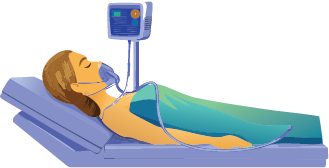

## Further Exploration

Explore the[ Medical Ventilator With Lung Model ](https://www.mathworks.com/help/simscape/ug/medical-ventilator-with-lung-model.html)example.

## Glossary

**Least-squares regression: **a method for finding the function, which is usually a line, that best fits a set of data points. (↑ Return to Text)

**Regression line: **a straight line that best represents the relationship between variables in a linear regression model, which shows predicted values based on the model. (↑ Return to Text)

**Residual:** a measure of the differences between actual data points and the values predicted by a regression model. (↑ Return to Text)

**Simple linear regression: **a model of the relationship between two variables using a straight line, with one independent variable predicting one dependent variable. (↑ Return to Text)

**Sum of squared errors **(**SSE**): the total of all squared residuals, which measures how well a model fits the data. (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternatively, select **Output inline **using the icon   at the top right of the Live Editor pane.

function [hFit,hRes] = RegressFit(x,y,Fit)
% function to visualize residuals on linear fit

% Regression line
hFit = plot(x,Fit,"-",LineWidth=2,SeriesIndex="none",DisplayName="Fit");

% Plot residuals
n = length(x);
hRes = gobjects(n,1); % Preallocate

for i = 1:n
    hRes(i) = plot([x(i) x(i)],[Fit(i) y(i)],"--",SeriesIndex="none");

    % Legend control (ONLY first residual)
    if i == 1
        hRes(i).DisplayName = "Residuals";
    else
        hRes(i).HandleVisibility = "off";
    end
end
end

function hScatter = ScatterPlot(x,y)
hScatter = scatter(x,y,"filled",SeriesIndex=3,MarkerFaceAlpha=0.6); % Create scatter plot
box on
xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
axis padded
end

function CheckAnswer(exerciseID,option)
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1",struct("answer","Fit 1: y = 2.075*x + 0.7629","hint","Which fit has the lowest SSE value and appears to fit the data best?"),...
    "Exercise2",struct("answer","y = 2.075 + 0.7029","hint", "Which fit minimizes the SSE value?"),...
    "Exercise3",struct("answer","$264,116","hint","What is the price for 1,864 sqft. ?"));

% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.");
    elseif isequal(option,"Select")
        warning("Select a valid option.");
    else
        warning("%s",hint);
    end
else
    warning("Exercise not found.");
end
end

function [yEquations,FitOptions] = SetEquations(x)
% Create a structure with all the fit data
yFit1 = 2.075*x + 0.7629;
yFit2 = 3.075*x + 0.5629;
yFit3 = 2.575*x + 0.6629;
yFit4 = 2.775*x + 0.6129;
yFit5 = 2.275*x + 0.7129;
yDefault = 0*x;

% LaTeX versions of the equations
latexEq1 = "Fit 1: y = 2.075*x + 0.7629";
latexEq2 = "Fit 2: y = 3.075*x + 0.5629";
latexEq3 = "Fit 3: y = 2.575*x + 0.6629";
latexEq4 = "Fit 4: y = 2.775*x + 0.6129";
latexEq5 = "Fit 5: y = 2.275*x + 0.7129";

yEquations = {"Select",latexEq1,latexEq2,latexEq3,latexEq4,latexEq5};

FitOptions = struct( ...
    "yFit",{yDefault,yFit1,yFit2,yFit3,yFit4,yFit5},...
    "FitEquation",yEquations,...
    "FitLabel",{"Default","Fit 1","Fit 2","Fit 3","Fit 4","Fit 5"} ...
    );
end

function T = compareFits(x,y,Fit,Plot,Table)

arguments
    x (:,1) double
    y (:,1) double
    Fit
    Plot (1,1) logical = true
    Table (1,1) logical = true
end

%% ---- Layout (robust) ----
if Plot && Table
    figure
    t = tiledlayout(1,2,TileSpacing="compact",Padding="compact");
    axPlot  = nexttile(t,1);
    axTable = nexttile(t,2);
elseif Plot
    figure
    axPlot  = axes;
    axTable = [];
elseif Table
    figure
    axTable = axes;
    axPlot  = [];
else
    return
end

%% ---- Compute fits ----
[yEquations,FitOptions] = SetEquations(x);

nFits = numel(FitOptions);

% Deterministic colors
fitColors = lines(nFits);

fitLabels = strings(nFits,1);
SSEvals   = nan(nFits,1);

for k = 1:nFits
    fitLabels(k) = FitOptions(k).FitEquation;
    SSEvals(k) = sum((y - FitOptions(k).yFit).^2);
end

T = table(fitLabels,SSEvals,VariableNames=["Fit","SSE"]);
Tdisp = T(2:end,:);

%% ---- TABLE ----
if Table
    axes(axTable)
    axis(axTable,"off")
    axTable.XLim = [0 1];
    axTable.YLim = [0 1];

    header = sprintf("%-25s %12s","Fit","SSE");
    text(axTable,0,0.95,header,FontName="monospaced",FontWeight="bold",FontSize=11,VerticalAlignment="top");

    dy = 0.07;
    y0 = 0.88;
    rowText = gobjects(height(Tdisp),1);

    for k = 1:height(Tdisp)
        rowStr = sprintf("%-25s %12.3g",Tdisp.Fit(k), Tdisp.SSE(k));

        rowText(k) = text(axTable,0,y0-(k-1)*dy,rowStr,FontName="monospaced",FontSize=10,VerticalAlignment="top", ...
            PickableParts="all",HitTest="on",ButtonDownFcn=@(~,~)plotSelectedFit(k+1));
    end

    title(axTable,"\bf{Fit Comparison}",Interpreter="latex")
    axTable.TitleHorizontalAlignment = "left";
end

%% ---- PLOT ----
if ~Plot
    return
end

axes(axPlot)
scatter(axPlot,x,y,"filled",MarkerFaceAlpha=0.6,DisplayName="Data");

xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
box on
axis padded
hold on

hFit = gobjects(1);
hRes = gobjects(0);

% ---- Selection logic ----
if iscell(Fit)
    FitIdx = find(Fit{1} == [yEquations{:}],1);

    if isempty(FitIdx)
        warning("Select a valid option.")
        return
    end

    plotSelectedFit(FitIdx)

elseif isnumeric(Fit) || islogical(Fit)
    selectedIdx = find(Fit);

    for idx = selectedIdx(:)'
        plot(axPlot,x,FitOptions(idx).yFit,LineWidth=2,Color=fitColors(idx,:),DisplayName=FitOptions(idx).FitEquation);
    end
else
    error("Fit must be logical, numeric, or cell of labels.")
end

legend("show",Location="northwest",Interpreter="latex")
hold off

%% ---- Callback ----
    function plotSelectedFit(idx)

        if isempty(axPlot) || ~isgraphics(axPlot)
            return
        end

        if isgraphics(hFit)
            delete(hFit)
        end
        if ~isempty(hRes) && all(isgraphics(hRes))
            delete(hRes)
        end

        axes(axPlot)
        hold(axPlot,"on")

        [hFit,hRes] = RegressFit(x,y,FitOptions(idx).yFit);

        %  Enforce deterministic color
        set(hFit,Color=fitColors(idx,:),DisplayName=FitOptions(idx).FitEquation);
        legend(axPlot,"show")
        hold(axPlot,"off")

        if Table
            set(rowText,FontWeight="normal")
            rowText(idx-1).FontWeight = "bold";
        end
    end

end

function ConfInt
% Modernized MATLAB example: comparing narrow vs wide confidence intervals
% Author: Cleve Moler–style example, updated for R2024b
% Modified by: Wynter Duncanson

% Generate reproducible results
rng default

% Create a tiled layout for side-by-side comparison
figure
t = tiledlayout(1,2,TileSpacing="compact",Padding="compact");

% ---- Tile 1: Narrow CI ----
nexttile
xSmall = linspace(-5,5,50);
ySmall = 2*xSmall + 3 + randn(size(xSmall));

% Fit model and get predictions with confidence intervals
MdlSmall = fitlm(xSmall,ySmall);
[xPred,~] = sort(xSmall);
[yPred,yCI] = predict(MdlSmall,xPred');

% Plot data and regression line
scatter(xSmall,ySmall,40,"filled",MarkerFaceAlpha=0.5,SeriesIndex=3)
hold on
fill([xPred fliplr(xPred)],[yCI(:,1)' fliplr(yCI(:,2)')], ...
    [0.4 0.6 0.8],EdgeColor="none",FaceAlpha=0.4)
plot(xPred,yPred,"-",SeriesIndex="none")
hold off
xlabel("x",Interpreter="latex")
ylabel("y",Interpreter="latex")
title("Good Fit: Narrow 95% CI")
box on
grid on

% ---- Tile 2: Wide CI ----
nexttile
xLarge = linspace(-5,5,50);
yLarge = 2*xLarge + 3 + randn(size(xLarge))*5;

MdlLarge = fitlm(xLarge,yLarge);
[xPred,~] = sort(xLarge);
[yPred,yCI] = predict(MdlLarge,xPred');

scatter(xLarge,yLarge,40,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3)
hold on
fill([xPred fliplr(xPred)],[yCI(:,1)' fliplr(yCI(:,2)')], ...
    [0.4 0.6 0.8],EdgeColor="none",FaceAlpha=0.4)
plot(xPred,yPred,"-",SeriesIndex="none")
hold off
xlabel("x")
ylabel("y")
title("Poor Fit: Wide 95% CI")
box on
grid on

% Add overall title
title(t,"Visual Comparison of 95% Confidence Intervals")

% Adjust fonts
set(findall(gcf,'-property','FontSize'),FontSize=12)
end

function evaluateLinearFit(x,y,b1Guess,b0Guess)
% Evaluate linear fit guess vs least-squares solution
arguments
    x (:,1) double
    y (:,1) double
    b1Guess double {mustBeReal}
    b0Guess double {mustBeReal}
end

scatter(x,y,"filled",DisplayName="Data",SeriesIndex=3);
box on
xlabel("x",Interpreter="latex")
ylabel("y",Interpreter="latex")
axis padded
hold on
% Plot user guess fit
plotFitLine(x,b1Guess,b0Guess,"--","Your Model")
legend("show",Location="best")
hold off
% Compute True Least Squares Fit
[b1True,b0True] = computeLeastSquares(x,y);

% Compute SSE for guess
sseGuess = computeSSE(x,y,b1Guess,b0Guess);
drawnow
% Display feedback and results
displayFeedback(b1Guess,b0Guess,b1True,b0True)
createSummaryTable(b1Guess,b0Guess,sseGuess)

% If guess is near true, show extra comparisons
if isClose(b1Guess,b1True,1e-3) && isClose(b0Guess,b0True,1e-3)
    compareOtherFits(x,y,b1True,b0True)
end
end

%% Helper Functions

function [b1,b0] = computeLeastSquares(x,y)
xbar = mean(x);
ybar = mean(y);
b1 = sum((x - xbar) .* (y - ybar)) / sum((x - xbar).^2);
b0 = ybar - b1*xbar;
end

function sse = computeSSE(x,y,m,b)
yhat = m*x + b;
sse = sum((y - yhat).^2);
end

function plotFitLine(x,m,b,style,label)
yfit = m*x + b;
plot(x,yfit,style,LineWidth=2,DisplayName=label);
end

function displayFeedback(b1Guess,b0Guess,b1True,b0True)
tol = 1e-3;
nearTol = 5e-2;

% Feedback for slope
disp(createParamFeedback(b1Guess,b1True,"slope",tol,nearTol));

% Feedback for intercept
disp(createParamFeedback(b0Guess,b0True,"intercept",tol,nearTol));
end

function msg = createParamFeedback(guess,truth,name,tol,nearTol)
diff = guess - truth;
if abs(diff) < tol
    msg = sprintf("You got the correct %s.",name);
elseif abs(diff) < nearTol
    if diff > 0
        msg = sprintf("The %s is slightly too high. Very close!",name);
    else
        msg = sprintf("The %s is slightly too low. Very close!",name);
    end
else
    if diff > 0
        msg = sprintf("The %s is too high. Try again.",name);
    else
        msg = sprintf("The %s is too low. Try again.",name);
    end
end
end

function tf = isClose(a,b,tolerance)
tf = abs(a - b) < tolerance;
end

function createSummaryTable(b1,b0,sse)
Model = sprintf("y = %.4gx + %.4g",b1,b0);
disp(table(Model,sse,VariableNames=["Model","SSE"]))
end

function compareOtherFits(x, y, b1True, b0True)
% Candidate values (edit once, logic scales automatically)
b1Candidates = [2.075 2.275 2.575 3.075];
b0Candidates = [0.5629 0.6129 0.6629 0.7129];

% Create all (b1, b0) combinations
[B1, B0] = ndgrid(b1Candidates,b0Candidates);

b1All = B1(:);
b0All = B0(:);

% Exclude the true least-squares model
tol = 1e-12;
isTrueModel = abs(b1All - b1True) < tol & abs(b0All - b0True) < tol;

b1All(isTrueModel) = [];
b0All(isTrueModel) = [];

% Compute SSE for all remaining models
nModels = numel(b1All);
SSE = zeros(nModels,1);

for k = 1:nModels
    SSE(k) = computeSSE(x,y,b1All(k),b0All(k));
end

% Create readable model labels
Model = arrayfun(@(m,b) sprintf("y=%.4gx + %.4g",m,b),b1All,b0All,UniformOutput=true);

% Display table
T = table(Model(:),SSE,VariableNames=["Other_Model","SSE"]);

disp(T)
end